## `GC Problem`

`Author: aleksander.grm@fpp.uni-lj.si, 20/02/2020`

#### `First Problem:`

It shows demonstration how to use Matlab functions for GC and RL computations.

`Inputs:`

- departure position: $P_1=(\varphi_1,\lambda_1)$

- arrival position: $P_2=(\varphi_2,\lambda_2)$

`Outputs:`

- GC and RL Course: $\omega$

- GC and RL Distance: $D$

fi_1 = [45,33.6,0]; % [deg, min, sec]
la_1 = [15,47.2,0]; % [deg, min, sec]
fi_2 = [37,17.8,0]; % [deg, min, sec]
la_2 = -[102,27.4,0]; % [deg, min, sec]

% *** add src path ***
lp = pwd;
addpath(fullfile(lp,'src'));

[w1_gc, d_gc, fiv_gc, lav_gc] = GC_data(fi_1,la_1,fi_2,la_2);
fiv = deg2dms(fiv_gc);
lav = deg2dms(lav_gc);

[w1_rl, d_rl] = RL_P1_data(fi_1,la_1,fi_2,la_2);

fprintf('P1: %s\nP2: %s', print_position(fi_1,la_1), print_position(fi_2,la_2))

P1: φ = 45° 33.6' N, λ = 015° 47.2' E
P2: φ = 37° 17.8' N, λ = 102° 27.4' W

fprintf('GC: w1=%.2f\xB0, d=%.2f Nm\nP(v): %s', w1_gc, d_gc, print_position(fiv, lav))

GC: w1=314.68°, d=4816.02 Nm
P(v): φ = 60° 08.6' N, λ = 038° 23.1' W

fprintf('RL: \x03C9=%5.1f\xB0, d=%.2f Nm', w1_rl, d_rl)

RL: ω=264.7°, d=5330.71 Nm

fprintf('dist_RL - dist_GC = %.2f Nm', d_rl - d_gc)

dist_RL - dist_GC = 514.69 Nm

#### `Second problem:`

Find an arbirtary point at GC

Inputs:

- departure position: $P_1=(\varphi_1,\lambda_1)$

- arrival position: $P_2=(\varphi_2,\lambda_2)$

- longitude of arbitrary point: $\lambda_i$

Output:

- latitude or arbitrary point: $\varphi_i$

`Case 1:`

fi_1 = [36,0,0]; % [deg, min, sec]
la_1 = -[6,0,0]; % [deg, min, sec]
fi_2 = [25,0,0]; % [deg, min, sec]
la_2 = -[75,0,0]; % [deg, min, sec]

fprintf('P1: %s', print_position(fi_1, la_1))

P1: φ = 36° 00.0' N, λ = 006° 00.0' W

fprintf('P2: %s', print_position(fi_2, la_2))

P2: φ = 25° 00.0' N, λ = 075° 00.0' W


% *** add src path ***
lp = pwd;
addpath(fullfile(lp,'src'));

% Find GC parameters
[w1_gc, d_gc, fiv_gc, lav_gc] = GC_data(fi_1,la_1,fi_2,la_2);
fiv = deg2dms(fiv_gc);
lav = deg2dms(lav_gc);
fprintf('GC: w1=%.2f\xB0, d=%.2f Nm', w1_gc, d_gc)

GC: w1=280.12°, d=3555.49 Nm

fprintf('P_v: %s', print_position(fiv, lav))

P_v: φ = 37° 12.5' N, λ = 022° 53.3' W


% Find some point in between
la_i = [15,0,0]; % some arbitrary lambda in between
[fi_m, la_m] = GC_mid_point(fi_1,la_1,fi_2,la_2,la_i);
fprintf('P_i: %s', print_position(fi_m, la_m))

P_i: φ = 37° 08.3' N, λ = 015° 00.0' E

#### `Third problem:`

Completely determine GC, RL and midpoints on GC

Inputs:

- departure position: $P_1=(\varphi_1,\lambda_1)$

- arrival position: $P_2=(\varphi_2,\lambda_2)$

- longitude of mid-points: $\lambda_i$

Output:

- latitude or mid-points: $\varphi_i$

- RL approximation of GC: midpoint course, distance and total distance.

fi_1 = -[33,02,0]; % [deg, min, sec]
la_1 = -[71,37,0]; % [deg, min, sec]
fi_2 = -[41,30,0]; % [deg, min, sec]
la_2 = [174,30,0]; % [deg, min, sec]

% *** add src path ***
lp = pwd;
addpath(fullfile(lp,'src'));
    
% Generate np of mid points on GC
np = 30;
ll = get_midpoints(la_1,la_2,np);
lat = zeros(1,np+2);
long = zeros(1,np+2);

lat(1) = dms2deg(fi_1);
long(1) = dms2deg(la_1);
for k = 1:np
    [fi_m, la_m] = GC_mid_point(fi_1,la_1,fi_2,la_2,ll(:,k));
    lat(k+1) = dms2deg(fi_m);
    long(k+1) = dms2deg(la_m);
end
lat(np+2) = dms2deg(fi_2);
long(np+2) = dms2deg(la_2);

% prints RL to GC data on screen and in Excel file "voyage_plan.xlsx" 
print_RL_on_GC_mid_points(np,lat,long);

*** Route Data ***
P(start): φ = 33° 02.0' S, λ = 071° 37.0' W
P(end):   φ = 41° 30.0' S, λ = 174° 30.0' E

*** Great Circle Data ***
GC: ω=223.53°, d=5031.47 Nm
P_v: φ = 54° 43.8' S, λ = 134° 14.2' W

*** Rhumb Line Data ***
RL: ω=264.7°, d=5450.91 Nm

*** Rhumb Line Mid Points Data ***
(P1) -> (P2): φ = 33° 02.0' S, λ = 071° 37.0' W, φ = 36° 06.3' S, λ = 075° 17.4' W
RL: ω=224.6°, d=258.63 Nm

(P2) -> (P3): φ = 36° 06.3' S, λ = 075° 17.4' W, φ = 38° 51.0' S, λ = 078° 57.8' W
RL: ω=226.7°, d=240.23 Nm

(P3) -> (P4): φ = 38° 51.0' S, λ = 078° 57.8' W, φ = 41° 17.5' S, λ = 082° 38.3' W
RL: ω=229.0°, d=223.39 Nm

(P4) -> (P5): φ = 41° 17.5' S, λ = 082° 38.3' W, φ = 43° 27.2' S, λ = 086° 18.7' W
RL: ω=231.4°, d=208.20 Nm

(P5) -> (P6): φ = 43° 27.2' S, λ = 086° 18.7' W, φ = 45° 21.8' S, λ = 089° 59.1' W
RL: ω=234.0°, d=194.68 Nm

(P6) -> (P7): φ = 45° 21.8' S, λ = 089° 59.1' W, φ = 47° 02.4' S, λ = 093° 39.5' W
RL: ω=236.6°, d=182.75 Nm

(P7) -> (P8): φ = 47° 02.4' S, λ = 093° 39.5' W, φ 

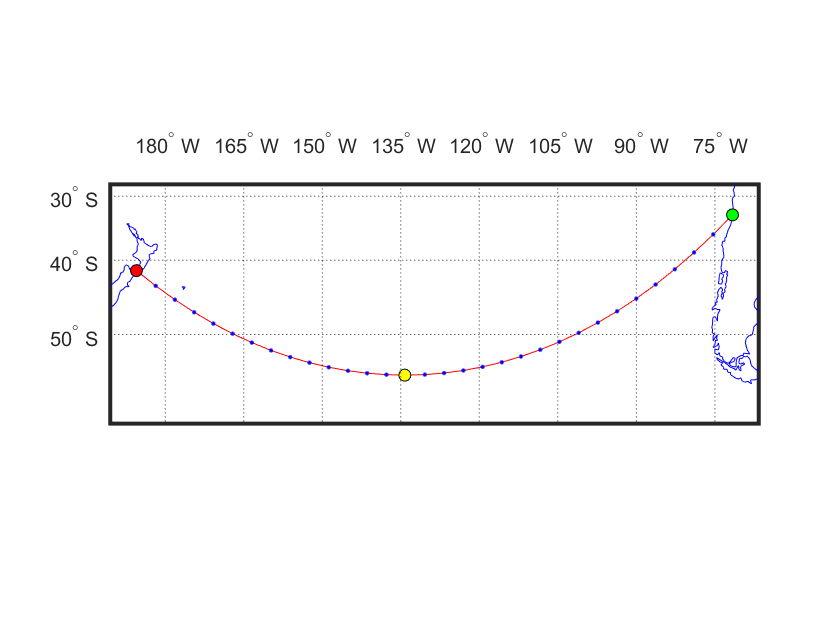


% plot Mercator chart
figure('color','w');
latWn = [(min(lat)-5), (max(lat)+5)];
dl = get_delta_long(long(1),long(end));
if dl < 0
    longWn = [long(end)-5, long(1)+5];
else
   longWn = [long(1)-5, long(end)+5]; 
end
axesm('mapproj','mercator',...
    'maplatlim',latWn ,'maplonlim', longWn,...
    'MLineLocation',15,'PLineLocation',10);
axis off, gridm on, framem on; mlabel on; plabel on;
% Load coastline data and plot it in the figure.
load coastlines;
hg = geoshow(coastlat,coastlon,'displaytype','line','color','b');
geoshow(lat,long,'displaytype','line','color','r',...
    'markeredgecolor','b','markerfacecolor','r','marker','.');
geoshow(dms2deg(fi_1),dms2deg(la_1),'DisplayType','point',...
    'markeredgecolor','k','markerfacecolor','g','marker','o')
geoshow(dms2deg(fi_2),dms2deg(la_2),'DisplayType','point',...
    'markeredgecolor','k','markerfacecolor','r','marker','o')
geoshow(fi_vgc,la_vgc,'DisplayType','point',...
    'markeredgecolor','k','markerfacecolor','y','marker','o')
tightmap

**Neerds stuff:**

Find maxima distance difference for RL and GL

N=1000;
dfi = 10/N;
fi_b = 35;
la1 = [0,0,0];
la2 = [180,0,0];

data = zeros(2,N);
for i = 1:N
    fi = deg2dms(fi_b + i*dfi);
    [w1_gc, d_gc, fiv_gc, lav_gc] = GC_data(fi,la1,fi,la2);
    [w1_rl, d_rl] = RL_P1_data(fi,la1,fi,la2);
  
  data(:,i) = [fi_b + i*dfi, d_rl - d_gc];
end

idx = find(abs(data(2,:)-max(data(2,:))) < 1e-8);
fi_max = deg2dms(data(1,idx));
fprintf('max_Dif_dist=%.2f, max_fi=%+d\xB0 %.2f\x27',data(2,idx), fi_max(1), fi_max(2)+fi_max(3)/60)

max_Dif_dist=2273.55, max_fi=+39° 32.40'

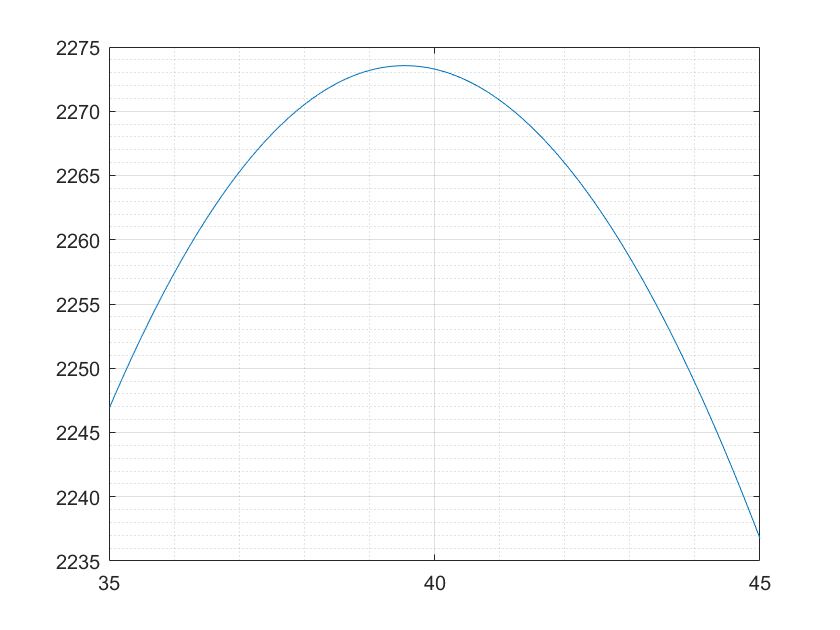


figure
plot(data(1,:),data(2,:))
grid on
grid minor